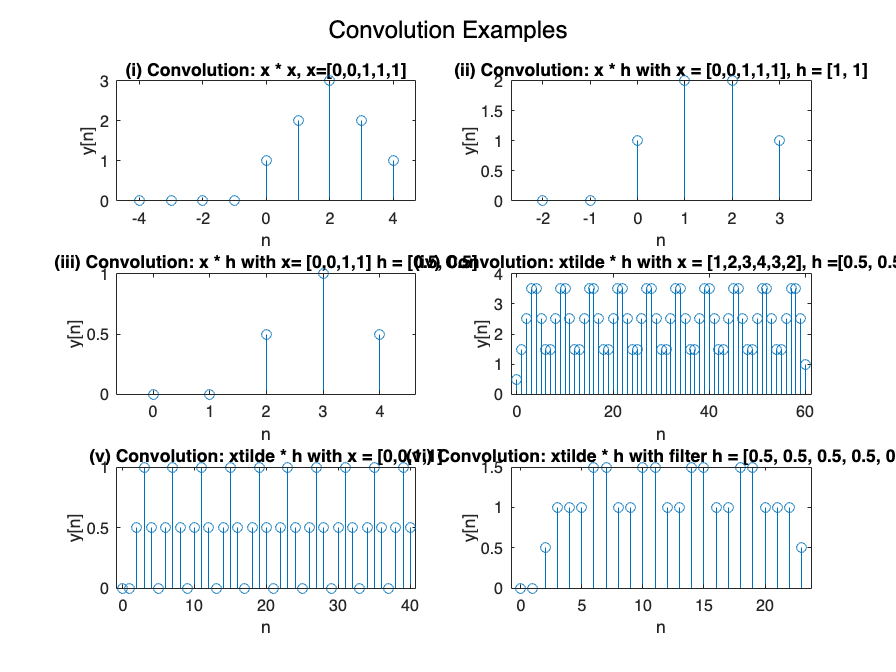

figure;

% i) y = x * x, with x = [0, 0, 1, 1, 1]
x = [0,0,1,1,1];
nx = -2:2;
[y, ny] = convolve(x, x, nx, nx);
subplot(3,2,1);
stem(ny, y);
title('(i) Convolution: x * x, x=[0,0,1,1,1]');
xlabel('n');
ylabel('y[n]');

% ii) y = x * h, with x = [0, 0, 1, 1, 1] and h = [1, 1]
x = [0,0,1,1,1];
nx = -2:2;
h = [1,1];
nh = 0:1;
[y, ny] = convolve(x, h, nx, nh);
subplot(3,2,2);
stem(ny, y);
title('(ii) Convolution: x * h with x = [0,0,1,1,1], h = [1, 1]');
xlabel('n');
ylabel('y[n]');

% iii) y = x * h, with x = [0, 0, 1, 1] and h = [0.5, 0.5]
x = [0,0,1,1];
nx = 0:3;
h = [0.5,0.5];
nh = 0:1;
[y, ny] = convolve(x, h, nx, nh);
subplot(3,2,3);
stem(ny, y);
title('(iii) Convolution: x * h with x= [0,0,1,1] h = [0.5, 0.5]');
xlabel('n');
ylabel('y[n]');

% iv) y = x * h, with x = [1,2,3,4,3,2] and h = [0.5, 0.5]
x = [1,2,3,4,3,2];
xtilde = repmat(x, 1, 10);
nx = 0: length(xtilde) - 1;
h = [0.5, 0.5];
nh = 0:1;
[y, ny] = convolve(xtilde, h, nx, nh);
subplot(3,2,4);
stem(ny, y);
title('(iv) Convolution: xtilde * h with x = [1,2,3,4,3,2], h =[0.5, 0.5]');
xlabel('n');
ylabel('y[n]');

% v) y = x * h, with x = [0,0,1,1] and h = [0.5, 0.5]
x = [0,0,1,1];
xtilde = repmat(x, 1, 10);
nx = 0: length(xtilde) - 1;
h = [0.5, 0.5];
nh = 0:1;
[y, ny] = convolve(xtilde, h, nx, nh);
subplot(3,2,5);
stem(ny, y)
title('(v) Convolution: xtilde * h with x = [0,0,1,1]')
xlabel('n');
ylabel('y[n]');


% a periodic signal convolved with a simple linear filter will produce a periodic output.
x = [0, 0, 1, 1];
xtilde = repmat(x, 1, 5); % Repeat the signal
nx = 0: length(xtilde) - 1;

% Filter h longer than the period of x
h = [0.5, 0.5, 0.5, 0.5, 0.5];
nh = 0: length(h) - 1;

[y, ny] = convolve(xtilde, h, nx, nh);

subplot(3,2,6);
stem(ny, y);
title('(vi) Convolution: xtilde * h with filter h = [0.5, 0.5, 0.5, 0.5, 0.5]');
xlabel('n');
ylabel('y[n]');

% Display the figure
% the periodicity breaks in the 6th subplot when the filter becomes longer than the period of the signal
% when the filter is longer than the signal in the time domain, you
% introduce something like "aliasing in the time domain".
sgtitle('Convolution Examples');